clear
clc

system("make clean -f .\Makefile");

rm -f *.exe
rm -f libs\*.exe
rm -f A_sparse.txt b.txt x.txt


system("make main -f .\Makefile");

g++ -Wall -Wpedantic FiniteDifferences.cpp -O2 -o FiniteDifferences.exe


N = 400

N = 400

M = N;
system(".\FiniteDifferences.exe " + string(N) + " " + string(M));

v1.x = round((131.25)/400 * N);
v1.y = round((125)/250 * N);
v2.x = round((400-131.25)/400 * N);
v2.y = round((125)/250 * N);

v3.x = round((151.39)/400 * N);
v3.y = round((250 - 76.39)/250 * N);
v4.x = round((400 - 151.39)/400 * N);
v4.y = round((76.39)/250 * N);

x = load("x.txt");

DV1 = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))) * 1e6 %[μV]

DV1 = 58.5393

DV2 = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))) * 1e6 %[μV]

DV2 = 38.7839

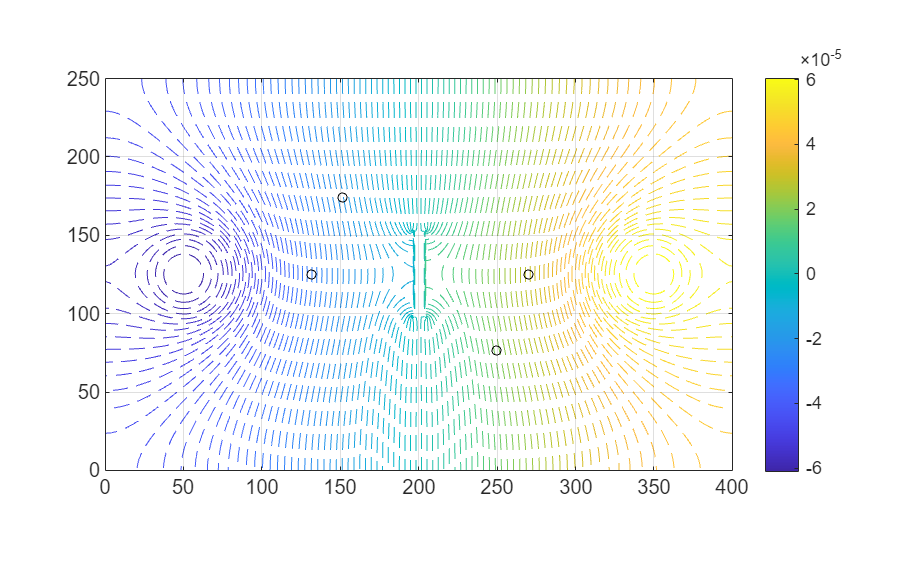

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

% psi = zeros(M,N);
% for i = 3:N
%     for j = 3:M-1
%         psi(j,i) = 1/3 * (4*psi(j-1,i) - psi(j-2,i) + (3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2)));
%         psi(j,i) = min(psi(j,i),1e-7);
%         psi(j,i) = max(psi(j,i),-1e-7);
%     end
% end

figure("Position",2*[0,0,400,250]);
X_range = linspace(0,400,size(phi,2));
Y_range = linspace(0,250,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,100, ...
    'LineStyle',"--", ...
    "fill","off")
hold on
% contour(X_range(3:end),Y_range(3:end),psi(3:end,3:end),300, ...
%     'LineStyle',":",'LineColor','k')
% hold on
sz = 20;
scatter(Dx*v1.x,Dy*v1.y,sz,'ko')
scatter(Dx*v2.x,Dy*v2.y,sz,'ko')
scatter(Dx*v3.x,Dy*v3.y,sz,'ko')
scatter(Dx*v4.x,Dy*v4.y,sz,'ko')
% xticks(X_range(1) : X_range(end)/10 : X_range(end))
% yticks(Y_range(1) : Y_range(end)/10 : Y_range(end))
hold off
grid on
axis equal
colorbar()